# **Data Products**

**Author:** Alexander Dunn

**Date:** 02/03/23

**Description: **This script further processes data and outputs the median distance measurements over user defined time intervals.

## Setup

This script takes a median of the distances measured over a set width interval of time. The interval can be specified here in minutes.

clear;
folder = "/Users/alexanderdunn/Desktop/Work/Data Sets/Cayucos 21-Jan-23/Gauge G"; % <--- Filepath to device folder

## Load Gauge Data

This section imports the data from the **allData.txt** file produced by the **waterSense_preprocess.mlx** file.

myMinutes = [5; 10; 15; 30; 60];
headerlinesIn = 15;
delimiterIn = ',';


Filepath = folder + "/Data Products/allData.txt";
Data = importdata(Filepath,delimiterIn,headerlinesIn);

Times = Data.data(:,1);
Times = datetime(Times, 'ConvertFrom', 'posixtime','Format','dd-MMM-yyyy HH:mm:ss.SSS');
Dists = Data.data(:,2);
Temps = Data.data(:,3);
Hums = Data.data(:,4);

## Slice Time Array

The timestamp array is split into sections centered on the minute interval specified above.

medianDists = nan(length(Times), length(myMinutes));
medianTimes = NaT(length(Times), length(myMinutes));
numPoints = nan(length(Times), length(myMinutes));

for set = 1:length(myMinutes)
    startTime = dateshift(Times(1), "start", "day") - minutes(myMinutes(set)/2);
    endTime = Times(end);
    timePoints = startTime:minutes(myMinutes(set)):endTime;
    startTimes = timePoints(1:end-1);
    endTimes = timePoints(2:end);
    
    slicedIndeces = nan(length(timePoints)-1, 2);
    currentIndex = 1;
    
    slicedIndeces(1,1) = 1;
    slicedIndeces(1,2) = 1;
    
    tic;
    for i = 2:(length(timePoints)-1)
        eidx = find(Times(currentIndex:end) >= endTimes(i), 1, "first") + currentIndex - 1;
        sidx = slicedIndeces(i-1,2);
        
        slicedIndeces(i,1) = sidx;
        slicedIndeces(i,2) = eidx;
        currentIndex = eidx;
    end

## Get Data

The median distances over each interval are calculated here.

    for i = 1:length(timePoints)-1
        numPoints(i, set) = slicedIndeces(i,2) - slicedIndeces(i,1);
    
        sampleTimes = Times(slicedIndeces(i,1):slicedIndeces(i,2));
        sampleDists = Dists(slicedIndeces(i,1):slicedIndeces(i,2));
    
        filteredDists = smoothdata(sampleDists, "movmedian", length(sampleDists)/5, "omitnan");
    
        medianDists(i, set) = median(filteredDists);
        medianTimes(i, set) = median(sampleTimes);
    end
    fprintf("%d minute increment completed after %0.2f seconds\n", myMinutes(set), toc)
end

5 minute increment completed after 209.56 seconds
10 minute increment completed after 100.54 seconds
15 minute increment completed after 67.15 seconds
30 minute increment completed after 34.30 seconds
60 minute increment completed after 18.10 seconds


medianDists = round(medianDists);

## Plot Data

The original data is plotted and can be compared to the new processed data.

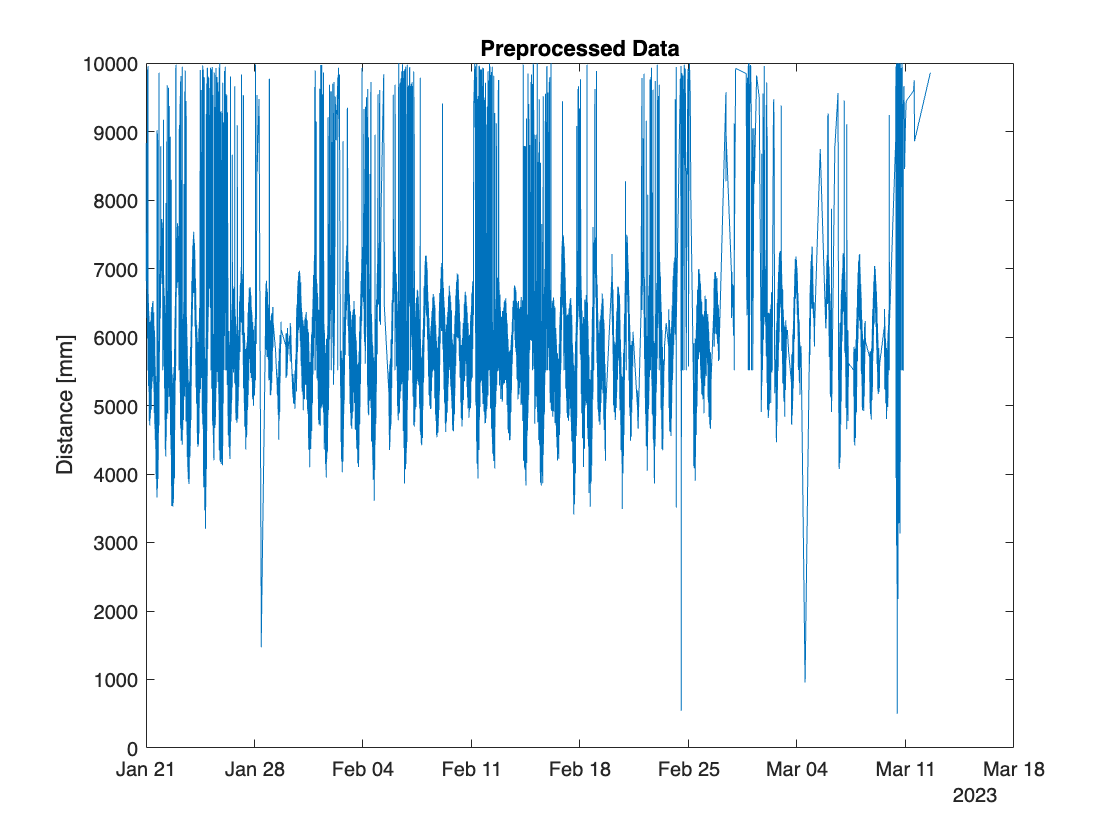

figure()
plot(Times, Dists)
title("Preprocessed Data")
ylabel("Distance [mm]")

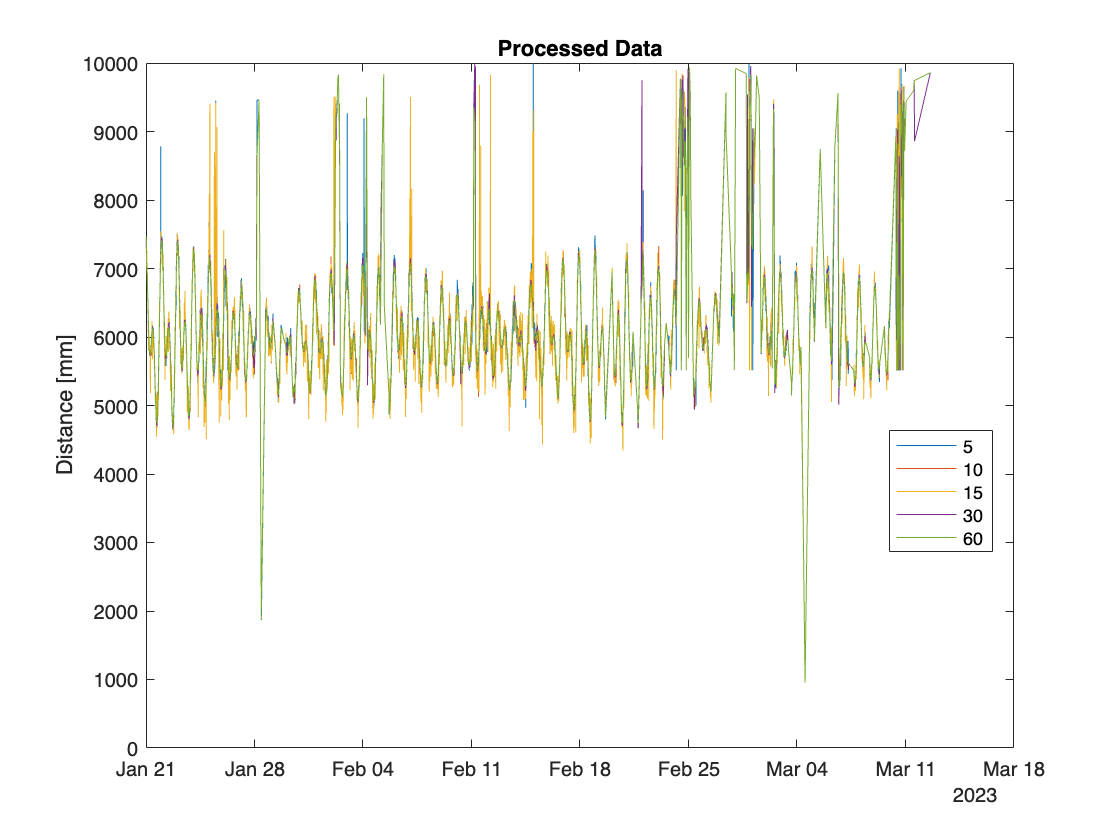

figure();
plot(medianTimes, medianDists)
title("Processed Data")
ylabel("Distance [mm]")
legend(string(myMinutes), "Location", "Best")

The number of data points used for each median is given as well.

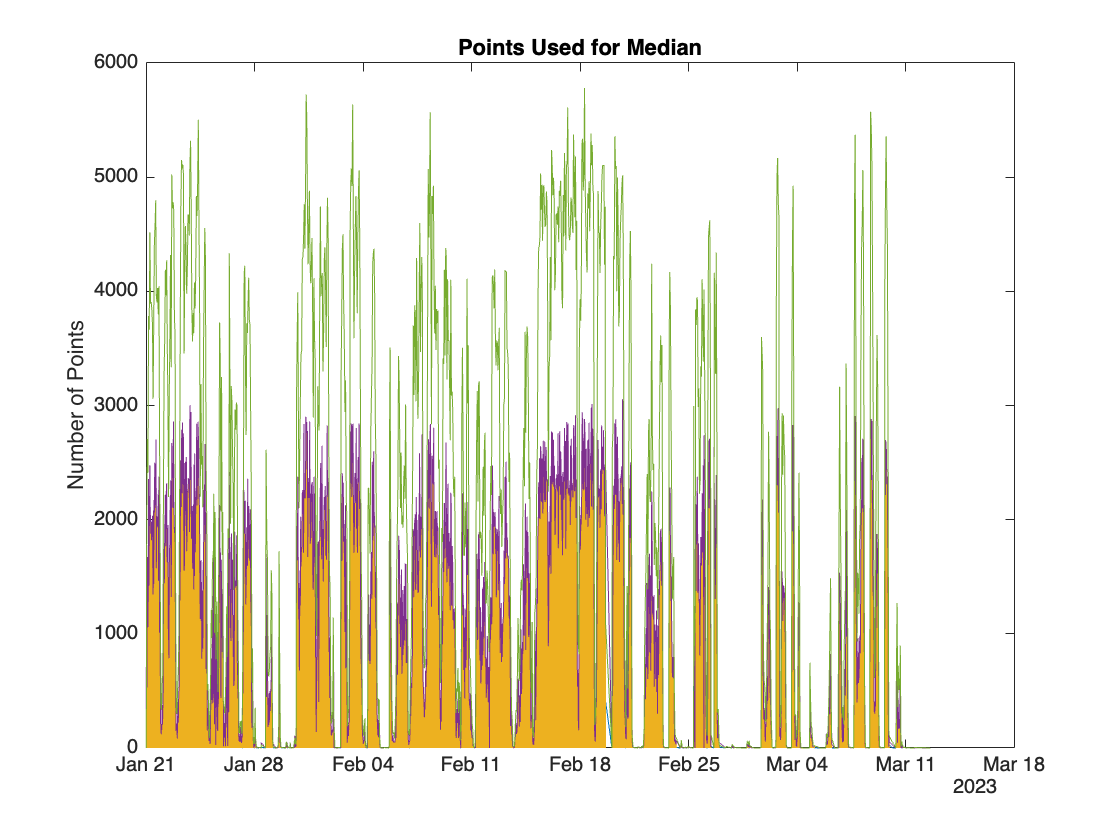

figure();
plot(medianTimes, numPoints)
title("Points Used for Median")
ylabel("Number of Points")


medianTimes = posixtime(medianTimes);


## Create File

Once the data has been properly filtered and sorted, a new text file can be written. Here information about the filtering process is written.

myHeader = Data.textdata(1:6,1);

for set = 1:length(myMinutes)
    tic;
    fileName = folder + "/Data Products/" + string(myMinutes(set)) + "_minuteData.txt";
    
    
    
    fid = fopen(fileName, "W");
    for i = 1:length(myHeader)
        fprintf(fid, "%s\n", string(myHeader(i)));
    end
    
    fprintf(fid, "Data QA:\n");
        fprintf(fid, "\tDistance measurements obtained assuming 25°C air temperature\n");
        fprintf(fid, "\tDistance measurements represent a median of measurements centered around %d minute intervals\n", myMinutes(set));
        fprintf(fid, "\tTime intervals with no data points are removed\n");
        fprintf(fid, "\n");
        fprintf(fid, "\n");
        fprintf(fid, "\n\n");
    
    fprintf(fid, "UNIX Timestamp [GMT], Distance from sensor to water [mm], Number of measurements used for median\n");
    
    n = length(medianTimes(:, set)); 
    for i = 1:n
        if (numPoints(i, set) > 0)
            fprintf(fid, "%0.3f,%d,%d\n", medianTimes(i, set), medianDists(i, set), numPoints(i, set));
        end
    end
    fclose(fid);
    fprintf("%d minute data written in %0.2f seconds\n", myMinutes(set), toc)
end

5 minute data written in 0.06 seconds
10 minute data written in 0.03 seconds
15 minute data written in 0.02 seconds
30 minute data written in 0.03 seconds
60 minute data written in 0.02 seconds
